clc;
clear;
close all;

%% NETWORK TOPOLOGY
% Client -> R1 -> R2 -> R3 -> R4 -> Server

num_routers = 4;
num_hops = num_routers + 1;  % links

%% PARAMETERS
sim_time = 5;        % seconds
dt = 0.001;
time = 0:dt:sim_time;

packet_rate = 10;    % packets/sec
packet_size = 1000;  % bits
link_rate = 1e6;     % 1 Mbps

%% DELAY MODEL
prop_delay = 0.002;  % propagation delay per link (sec)
queue_delay = zeros(1, num_hops);

%% STATE VARIABLES
packet_in_transit = zeros(1, num_hops);  % packet position in pipeline
arrival_time = [];
departure_time = [];

sent_packets = 0;
received_packets = 0;

%% SIMULATION LOOP

for t = 1:length(time)
    
    current_time = time(t);
    
    %% CLIENT GENERATES PACKETS
    if rand < packet_rate * dt
        
        sent_packets = sent_packets + 1;
        
        % inject packet at first hop
        packet_in_transit(1) = packet_in_transit(1) + 1;
        
        arrival_time = [arrival_time current_time];
    end
    
    %% MOVE PACKETS THROUGH ROUTERS
    for i = num_hops:-1:1
        
        if packet_in_transit(i) > 0
            
            % transmission time per hop
            tx_time = packet_size / link_rate;
            
            if i < num_hops
                % move to next hop
                packet_in_transit(i) = packet_in_transit(i) - 1;
                packet_in_transit(i+1) = packet_in_transit(i+1) + 1;
            else
                % reached server
                packet_in_transit(i) = packet_in_transit(i) - 1;
                received_packets = received_packets + 1;
                
                departure_time = [departure_time current_time];
            end
        end
    end
    
    %% PROPAGATION DELAY EFFECT (simple accumulation)
    queue_delay = queue_delay + prop_delay;
end

%% PERFORMANCE METRICS

end_to_end_delay = departure_time - arrival_time(1:length(departure_time));

avg_delay = mean(end_to_end_delay) * 1000; % ms

throughput = (received_packets * packet_size) / sim_time;

packet_loss = ((sent_packets - received_packets) / max(sent_packets,1)) * 100;

utilization = (received_packets / max(sent_packets,1)) * 100;

%% RESULTS

fprintf('--- CLIENT → ROUTERS → SERVER NETWORK ---\n');

--- CLIENT → ROUTERS → SERVER NETWORK ---


fprintf('Packets Sent = %d\n', sent_packets);

Packets Sent = 54


fprintf('Packets Received = %d\n', received_packets);

Packets Received = 54


fprintf('Throughput = %.2f bps\n', throughput);

Throughput = 10800.00 bps


fprintf('Packet Loss = %.2f %%\n', packet_loss);

Packet Loss = 0.00 %


fprintf('Average End-to-End Delay = %.4f ms\n', avg_delay);

Average End-to-End Delay = 4.0000 ms


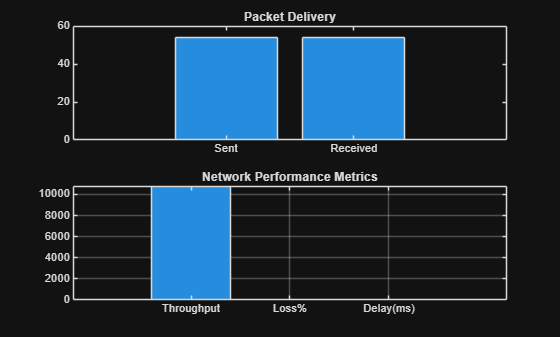


%% PLOTS

figure;

subplot(2,1,1);
bar([sent_packets received_packets]);
set(gca, 'XTickLabel', {'Sent','Received'});
title('Packet Delivery');

subplot(2,1,2);
bar([throughput packet_loss avg_delay]);
set(gca, 'XTickLabel', {'Throughput','Loss%','Delay(ms)'});
title('Network Performance Metrics');
grid on;